% 600100 Computer Vision
% ACW related: Object metrics and selection

% Aim of workshop: use of MSER and region properties to build region and feature models

% Minor aspects broken on purpose!

% section 0 is standard text extraction

% investigate parameters

% Note: If you are installing MATLAB at home. Don't worry too much about
% specific versions, install something that works.

% You are welcome to replace test images in here with ACW images.

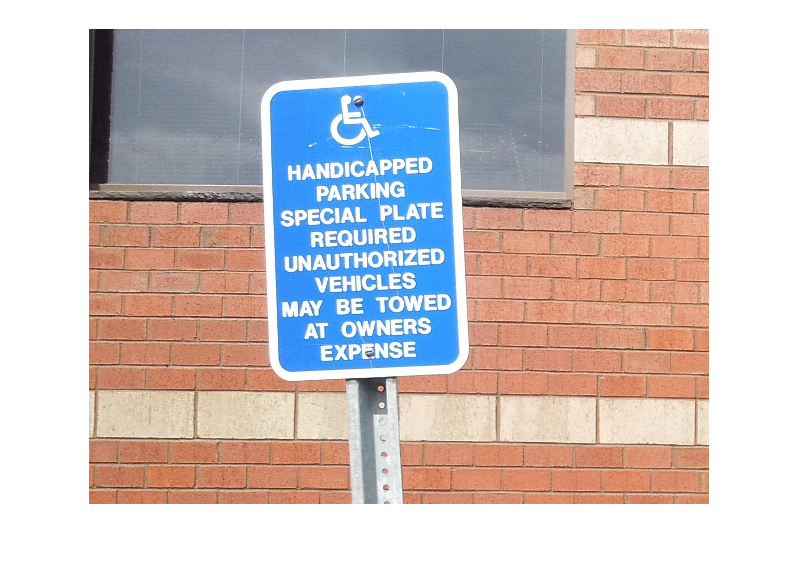

% Section 0: Matlab Example using stock image

% https://uk.mathworks.com/help/vision/examples/automatically-detect-and-recognize-text-in-natural-images.html
% Step 1: Detect Candidate Text Regions Using MSER
colorImage = imread('handicapSign.jpg');
I = rgb2gray(colorImage);
figure; imshow(colorImage);

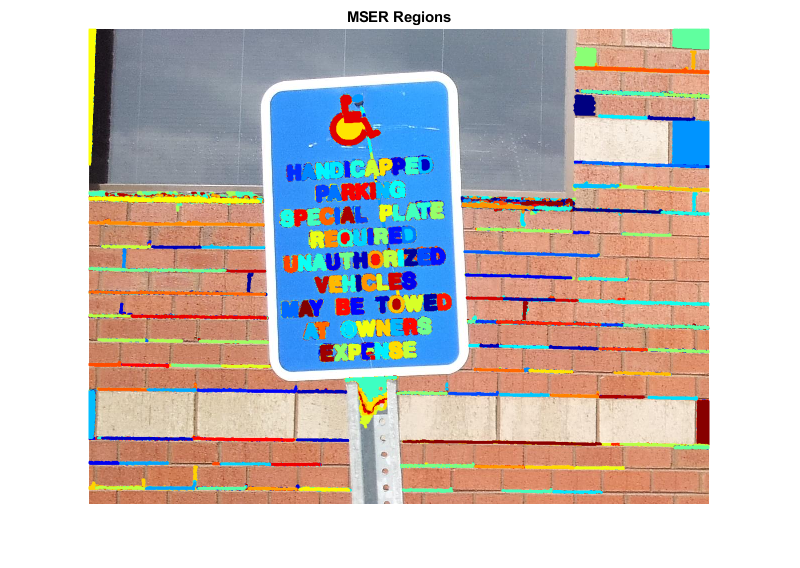


% Detect MSER regions.
% Maximally stable extremal regions
% Investigate parameters to detectMSERFeatures
% see https://uk.mathworks.com/help/vision/ref/detectmserfeatures.html 

%a) Pass RegionAreaRange between 200 and 8000; Threshold Delta to 4.
[mserRegions, mserConnComp] = detectMSERFeatures(I, 'RegionAreaRange',[200,8000]);

%b) Using plot, display the mserRegions. Remember any use of figure, hold.
% You will need to pass 'showPixelList', true & 'showEllipses, false to the
% plot function as options.
% Give the plot a title E.g "MSER Regions".
figure
imshow(colorImage);
title("MSER Regions");
hold on;
plot(mserRegions, 'showPixelList', true, 'showEllipses', false);
hold off;

 
 % Step 2: Remove Non-Text Regions Based On Basic Geometric Properties
 % Use regionprops to measure MSER properties (passing in connected
 % components from our MSER stage)
 mserStats = regionprops(mserConnComp, 'BoundingBox', 'Eccentricity', ...
     'Solidity', 'Image');
 
 % Compute the aspect ratio using bounding box data.
 
 % a) Using the mserStats BoundingBox results. Calculate your own metric.
 % Aspect Ratio. Which is defined as the width ./ Height.
 % Remember, each entry in mserStats is a distinct detection. You may wish
 % to use vertcat.
 % See https://uk.mathworks.com/help/images/ref/regionprops.html for
 % property definitions.
 bbox = vertcat(mserStats.BoundingBox);
 w = bbox(:, 3); % Which one gives width and height?
 h = bbox(:, 4);
 aspectRatio = w./h;
 
 % Threshold the data to determine which regions to remove.
 % These thresholds may need to be tuned for other images.
 filterIdx = aspectRatio' > 4; 
 filterIdx = filterIdx | [mserStats.Eccentricity] > .995 ;
 filterIdx = filterIdx | [mserStats.Solidity] < .3;
 
 % Remove regions
 mserStats(filterIdx) = [];
 mserRegions(filterIdx) = [];

Matrix index is out of range for deletion.

 
 % Show remaining regions
 figure
 imshow(I)
 hold on
 plot(mserRegions, 'showPixelList', true,'showEllipses',false)
 title('After Removing Non-Text Regions Based On Geometric Properties')
 hold off
 % end of section
 
 % b) Now we've done some basic filtering. Modify your regionprops call to
 % ask for Euler Number, and Extent.
 % Extend the filterIdx by filtering for Euler Number < -4
 % Extend the filterIdx by filtering for Extent < 0.2; OR Extent > 0.9
 % (Remember we can use | for boolean OR)

% % section 0:1
% clear; % and now clear workspace of all variables ready for region and feature metric investigation
% % end of section

% % Section 1: Select Source Image for Feature Descriptors
% % Load and assign images ready for later sections
% 
% % Use stock Matlab Image
% % Source = imread('cameraman.tif');
% 
% % alternatives are to import data into workspace
% % then assign Source to chosen image
% % all following sections rely on "Source" being correctly assigned
% % for example
% % Use four_objects.jpg
% % Source = four_objects;
% 
% % Use five_objects.jpg
% Source = five_objects; % You might find this on Canvas.
% 
% % Mars Crater - martesvallescrater.jpg
% % Source = martesvallescrater;

% % section 2: Combining Feature Descriptors and Region Detection Algorithms
% % Get grayscale version of source image
% % Assume only 3 plane or Intensity Source Images
% % modify for intensity-transparency 2 channel image etc.
% % or [~,~,ColorChannel] = size(img)
% if (ndims(Source) == 3) % Colour RGB image
%     Image = rgb2gray( Source );
%     figure; imshow(Source);
%     figure; imshow( Image );
% else
%     Image = Source;
%     figure; imshow( Image );
% end
% % Do some preprocessing if required
% % Image = imadjust( Image);
% % imshow( Image );
% % end of section

% % Section 3: MSER Algorithm
% % Built in function
% % Detect and store regions.
% 
% % Which one should you use? Do we need ConnComp here?
% [Regions, ConnComp] = detectMSERFeatures(Image);
% Regions = detectMSERFeatures(Image);
% 
% % Display the centroids and axes of detected regions.
% imshow(Image); hold on; plot(Regions); hold off;
% [Nregions, ~] = size( Regions );
% 
% % [~,idx]=sort([Regions.Area],'descend'); % this line is broken
% % - fix it to arrange regions in area. This will allow the First N to be
% % the largest ones.
% 
% % Other more sophisticated constraints can be developed
% % restrict regions to first one hundred
% % modify for more
% if (Nregions > 100) 
%     Nregions = 100;
% end
% 
% % Display the first Nregions regions in the MSER Regions object.
% imshow(Image); hold on;
% plot(Regions(1:Nregions),'showPixelList', true);
% % end of section

% % Extra Section if Logical Image from MSER regions required
% % Compare with thresholds using Image Region Analyser App
% maskall = false(size(Image));
% [Nregions, ~] = size(Regions);
% for i = 1:Nregions
%     [pixels, ~] = size(Regions(i).PixelList);
%     local = Regions(i).PixelList;
%     for j = 1:pixels
%         x = local(j,1);
%         y = local(j,2);
%         maskall(y, x) = true;
%     end
% end
% imshow(maskall);
% % Now use Image Region Analyser (in Apps) with the logical image
% % investigate different feature properties
% % end of section

% % Using Results of MSER to find objects via regionprops etc.
% % Use this section for five_objects.jpg or four_objects.jpg
% % properties = regionprops(, 'all'); % uncomment if all metrics required
% mserStats = regionprops(ConnComp, 'BoundingBox', 'Eccentricity', 'Solidity', 'Extent', 'Image');
% properties_table = regionprops('table',ConnComp, 'BoundingBox', 'Eccentricity', 'Solidity', 'Extent', 'Image');
% % show table
% properties_table
% 
% % following bundles of code select regions based on topologies to be found in "simple" synthetic images
% 
% % selecting circle
% BW_out = maskall;
% % Filter image based on image properties.
% % Vary the parameters in third argument
% BW_out = bwpropfilt(BW_out, 'Eccentricity', [0, 0.45]);
% BW_out = bwpropfilt(BW_out, 'Extent', [0.45, 0.85]);
% figure; hold on
% imshow(BW_out); title('Circle'); hold off;
% 
% % selecting five point star
% BW_out = maskall;
% % Filter image based on image properties.
% BW_out = bwpropfilt(BW_out, 'Eccentricity', [0, 0.5]);
% BW_out = bwpropfilt(BW_out, 'Extent', [0, 0.5]);
% figure; hold on
% imshow(BW_out); title('Five Point Star'); hold off;
% 
% % Selecting six point star
% BW_out = maskall;
% % Filter image based on image properties.
% BW_out = bwpropfilt(BW_out, 'Eccentricity', [0, 0.5]);
% BW_out = bwpropfilt(BW_out, 'Extent', [0, 0.55]);
% BW_out = bwpropfilt(BW_out, 'Solidity', [0.55, 1]);
% figure; hold on
% imshow(BW_out); title('Six Point Star'); hold off;
% 
% % Now try with different Source images
% % vary the properties look to feature selection in Image Region Analyser (in Apps) with the logical image

%eof